%Rigt is X (center toward lock button)
%up is Y (center toward camera)
%Front is Z (center toward mobile screen)
load('/home/hazem/MATLAB-Drive/MobileSensorData/sensorlog_SQUARE.mat');

% Accessing acceleration data
ax = Acceleration.X;
ay = Acceleration.Y;
az = Acceleration.Z;
accelTime = Acceleration.Timestamp;
acc_measured = [ax, ay, az];
% Accessing Angular Velocity data
wx = AngularVelocity.X;
wy = AngularVelocity.Y;
wz = AngularVelocity.Z;
gyroTime = AngularVelocity.Timestamp;
av_measured = [wx, wy, wz];

avt = seconds(diff(AngularVelocity.Timestamp));
at = seconds(diff(Acceleration.Timestamp)); 
sizeAccel = length(ax);
sizeAngVel = length(wx);

tolerance = seconds(0.01);  % Set tolerance

% Initialize a counter for matched frames
matchCount = 0;

% First, determine how many frames are matched within the tolerance
if avt(1) < at(1)  % If accelerometer data is less frequent
    for i = 1:length(accelTime)
        timeDifference = abs(gyroTime - accelTime(i));
        [minDiff, ~] = min(timeDifference);
        
        if minDiff <= tolerance
            matchCount = matchCount + 1;  % Increment match count
        end
    end
else  % If gyroscope data is less frequent
    for i = 1:length(gyroTime)
        timeDifference = abs(accelTime - gyroTime(i));
        [minDiff, ~] = min(timeDifference);
        
        if minDiff <= tolerance
            matchCount = matchCount + 1;  % Increment match count
        end
    end
end

% Now allocate arrays based on the number of matched frames
syncedAccelData = zeros(matchCount, 3);
syncedGyroData = zeros(matchCount, 3);
syncedTimestamps = datetime.empty(matchCount, 0);

% Reset match count for actual data synchronization
matchCount = 0;

% Synchronize data based on matched frames
if avt(1) < at(1)  % Accelerometer less frequent
    for i = 1:length(accelTime)
        timeDifference = abs(gyroTime - accelTime(i));
        [minDiff, idx] = min(timeDifference);

        if minDiff <= tolerance
            matchCount = matchCount + 1;
            syncedAccelData(matchCount, :) = acc_measured(i, :);  % Store accel data
            syncedGyroData(matchCount, :) = av_measured(idx, :);  % Store gyro data
            syncedTimestamps(matchCount) = accelTime(i);          % Store timestamp
        end
    end
else  % Gyroscope less frequent
    for i = 1:length(gyroTime)
        timeDifference = abs(accelTime - gyroTime(i));
        [minDiff, idx] = min(timeDifference);

        if minDiff <= tolerance
            matchCount = matchCount + 1;
            syncedAccelData(matchCount, :) = acc_measured(idx, :);  % Store accel data
            syncedGyroData(matchCount, :) = av_measured(i, :);      % Store gyro data
            syncedTimestamps(matchCount) = gyroTime(i);             % Store timestamp
        end
    end
end

% Calculate time differences and frequency
dt = seconds(diff(syncedTimestamps));
fs = 1 ./ dt;

%Filtering noise 
% Sampling frequency and cutoff frequency
fc = 0.05 * fs(1);  % Cutoff frequency for low-pass filter (1 Hz)

% Design a 2nd-order low-pass Butterworth filter
[b, a] = butter(4, fc / (fs(1) / 2), 'low');  % Low-pass filter
fillSyncedAccelData = filtfilt(b, a, syncedAccelData);  % Zero-phase filtering
fillSyncedGyroData = filtfilt(b, a, syncedGyroData);  % Zero-phase filtering



%Removing acceleration Bias
calibFrames = 250;
accBias = [mean(fillSyncedAccelData(1:calibFrames,1))    mean(fillSyncedAccelData(1:calibFrames,2))    (mean(fillSyncedAccelData(1:calibFrames,3)) - 9.81)];
corrFillSyncedAccelData = fillSyncedAccelData - accBias;
gyroBias = [mean(fillSyncedGyroData(1:calibFrames,1))   mean(fillSyncedGyroData(1:calibFrames,2))   mean(fillSyncedGyroData(1:calibFrames,3))];
corrFillSyncedGyroData = fillSyncedGyroData - gyroBias;


thetaX = cumsum(corrFillSyncedGyroData(:,1) * dt(1)); 
thetaY = cumsum(corrFillSyncedGyroData(:,2) * dt(1)); 
thetaZ = cumsum(corrFillSyncedGyroData(:,3) * dt(1)); 
theta = [thetaX thetaY thetaZ];

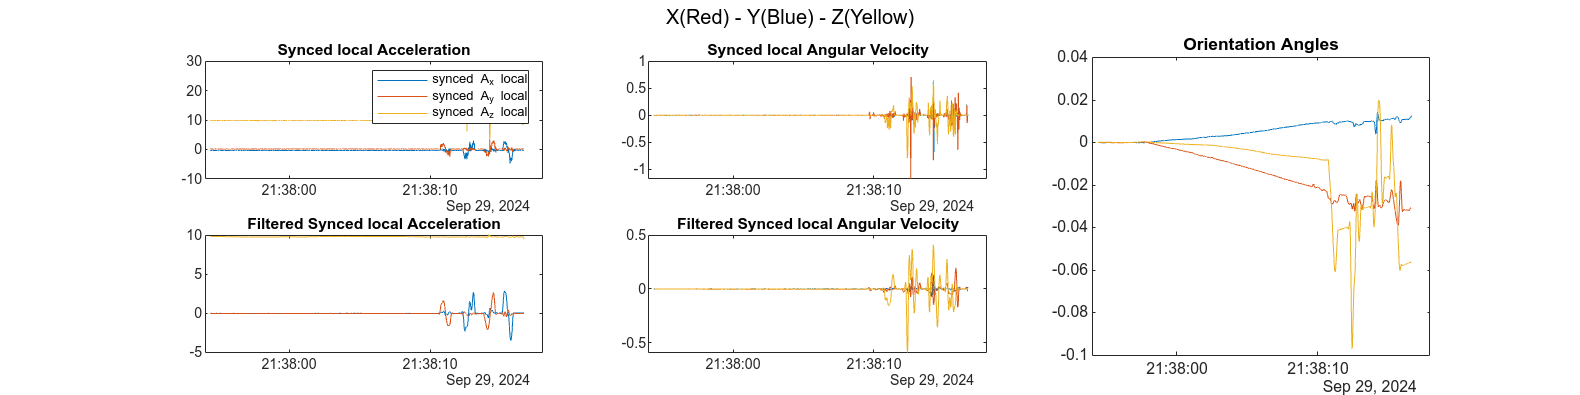

figure('Position', [800, 0, 3200, 800]);
subplot(2, 3, 1);
plot(syncedTimestamps,syncedAccelData(:,1));
hold on;
plot(syncedTimestamps,syncedAccelData(:,2));
plot(syncedTimestamps,syncedAccelData(:,3));
hold off;
legend("synced A_x local", "synced A_y local", "synced A_z local");
title("Synced local Acceleration")

subplot(2, 3, 2);
plot(syncedTimestamps,syncedGyroData(:,1));
hold on;
plot(syncedTimestamps,syncedGyroData(:,2));
plot(syncedTimestamps,syncedGyroData(:,3));
hold off;
%legend("synced w_x local", "synced w_y local", "synced w_z local");
title("Synced local Angular Velocity")

subplot(2, 3, 4);
plot(syncedTimestamps,corrFillSyncedAccelData(:,1));
hold on;
plot(syncedTimestamps,corrFillSyncedAccelData(:,2));
plot(syncedTimestamps,corrFillSyncedAccelData(:,3));
hold off;
%legend("theta_x local", "theta_y local", "theta_z local")
title("Filtered Synced local Acceleration")

subplot(2, 3, 5);
plot(syncedTimestamps,corrFillSyncedGyroData(:,1));
hold on;
plot(syncedTimestamps,corrFillSyncedGyroData(:,2));
plot(syncedTimestamps,corrFillSyncedGyroData(:,3));
hold off;
%legend("A_x global", "A_y global", "A_z global")
title("Filtered Synced local Angular Velocity")
subplot(2, 3, [3 6]);
plot(syncedTimestamps,theta(:,1));
hold on;
plot(syncedTimestamps,theta(:,2));
plot(syncedTimestamps,theta(:,3));
hold off;
% axes 5
%legend(["Theta_x", "Theta_y", "Theta_z"])
title("Orientation Angles")
sgtitle("X(Red) - Y(Blue) - Z(Yellow)")

function R_ortho = orthonormalize(R)
    [U, ~, V] = svd(R);
    R_ortho = U*V';
end

%Creating function to update orientation
function R_new = updateOrient(R_old, omega, deltaT)
    omega = omega(:); %to ensure its 3x1
    theta = norm(omega) * deltaT;
    if theta ~=0
        axis = omega / norm(omega);
        omega = [0, -axis(3), axis(2); axis(3), 0, -axis(1); -axis(2), axis(1), 0];
        R_rot = eye(3) + sin(theta)*omega + (1-cos(theta)) * (omega * omega);
        %Using RODRIGUES ROTATION FORMULA
        R_new = reshape(R_old,3,3) * R_rot;
    else
        R_new = reshape(R_old,3,3);
    end
    R_new = orthonormalize(R_new);
end


%Initializing data
Rglobal = zeros(length(syncedTimestamps), 3, 3);
Rglobal(1,:,:) = eye(3);

for i = 2:length(syncedTimestamps)
    Rglobal(i, :, :) = updateOrient(Rglobal(i-1, :, :),corrFillSyncedGyroData(i,:), dt(1));
end

% Preallocate arrays for global frame data
accelGlobal = zeros(length(syncedTimestamps), 3);
gyroGlobal = zeros(length(syncedTimestamps), 3);
globalGrav = [0 0 9.81];
% Loop through and rotate the data to the global frame
for i = 1:length(syncedTimestamps)
    % Extract current rotation matrix
    R = squeeze(Rglobal(i, :, :));  % Get the 3x3 rotation matrix for the i-th timestamp
    
    % Rotate the local accelerometer data to the global frame
    accelGlobal(i, :) = (R * corrFillSyncedAccelData(i, :)')' - (R * globalGrav')';  % Rotate accel to global frame
    
    % Optionally rotate the angular velocity data (though it may not be needed)
    gyroGlobal(i, :) = (R * corrFillSyncedGyroData(i, :)')';  % Rotate gyro to global frame
end

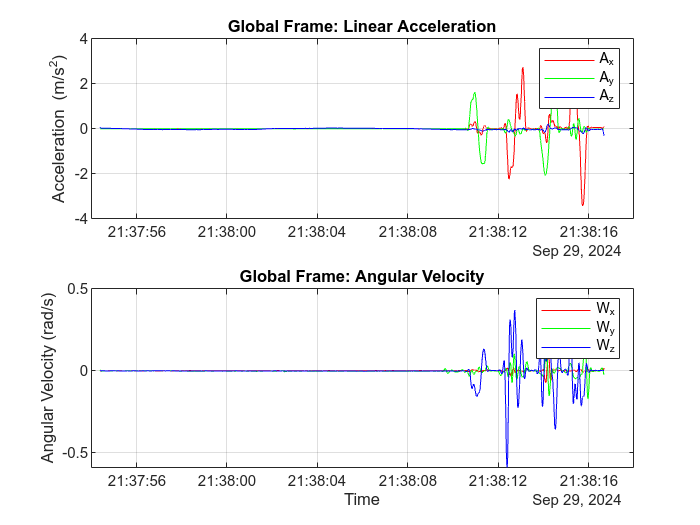

figure;
% Plot all acceleration components in one subplot
subplot(2,1,1);
plot(syncedTimestamps, accelGlobal(:,1), 'r', 'DisplayName', 'A_x'); hold on;
plot(syncedTimestamps, accelGlobal(:,2), 'g', 'DisplayName', 'A_y');
plot(syncedTimestamps, accelGlobal(:,3), 'b', 'DisplayName', 'A_z');
title('Global Frame: Linear Acceleration');
ylabel('Acceleration (m/s^2)');
legend;
grid on;

% Plot all angular velocity components in another subplot
subplot(2,1,2);
plot(syncedTimestamps, gyroGlobal(:,1), 'r', 'DisplayName', 'W_x'); hold on;
plot(syncedTimestamps, gyroGlobal(:,2), 'g', 'DisplayName', 'W_y');
plot(syncedTimestamps, gyroGlobal(:,3), 'b', 'DisplayName', 'W_z');
title('Global Frame: Angular Velocity');
ylabel('Angular Velocity (rad/s)');
xlabel('Time');
legend;
grid on;

accelGlobal = smoothdata(accelGlobal);
velGlobal = zeros(length(syncedTimestamps),3);
posGlobal = zeros(length(syncedTimestamps),3);
threshold = 0.15;
for i = 2:length(syncedTimestamps)
    % Update velocity (v_i+1 = v_i + a_i * dt)
    
    
    velGlobal(i,:) = velGlobal(i-1, :) + (accelGlobal(i-1, :) * dt(1)); 
    
    if norm(accelGlobal(i,1)) < threshold
        velGlobal(i,1) = velGlobal(i-1,1);  % Reset velocity to zero during stationary periods
    end
    if norm(accelGlobal(i,2)) < threshold
        velGlobal(i,2) = velGlobal(i-1,2);  % Reset velocity to zero during stationary periods
    end
    if norm(accelGlobal(i,3)) < threshold
        velGlobal(i,3) = velGlobal(i-1,3);  % Reset velocity to zero during stationary periods
    end
    
    % Update position (x_i+1 = x_i + v_i * dt)
    
    posGlobal(i,:) = posGlobal(i-1,:) + (velGlobal(i-1,:) * dt(1));
    
    if norm(velGlobal(i,1)) < threshold
        posGlobal(i,1) = posGlobal(i-1,1);  % Reset velocity to zero during stationary periods
    end
    if norm(velGlobal(i,2)) < threshold
        posGlobal(i,2) = posGlobal(i-1,2);  % Reset velocity to zero during stationary periods
    end
    if norm(velGlobal(i,3)) < threshold
        posGlobal(i,3) = posGlobal(i-1,3);  % Reset velocity to zero during stationary periods
    end
    


end



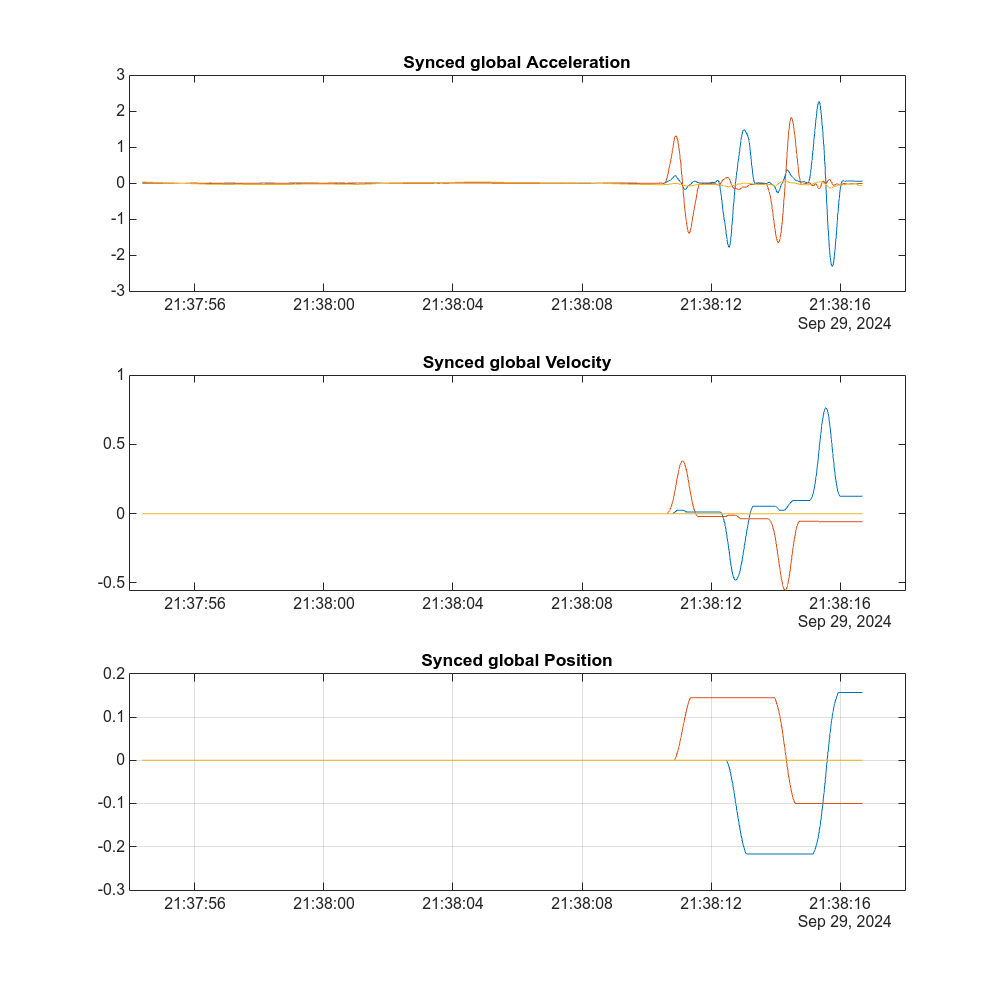

figure('Position', [0, 0, 2000, 2000]);
subplot(3, 1, 1);
plot(syncedTimestamps,accelGlobal(:,1));
hold on;
plot(syncedTimestamps,accelGlobal(:,2));
plot(syncedTimestamps,accelGlobal(:,3));
hold off;
%legend("A_x global", "A_y global", "A_z global")
title("Synced global Acceleration")

subplot(3, 1, 2);
plot(syncedTimestamps,velGlobal(:,1));
hold on;
plot(syncedTimestamps,velGlobal(:,2));
plot(syncedTimestamps,velGlobal(:,3));
hold off;
%legend("V_x global", "V_y global", "V_z global")
title("Synced global Velocity")

subplot(3, 1, 3);
plot(syncedTimestamps,posGlobal(:,1));
hold on;
plot(syncedTimestamps,posGlobal(:,2));
plot(syncedTimestamps,posGlobal(:,3));
hold off;
%legend("P_x global", "P_y global", "P_z global")
title("Synced global Position")

grid on;

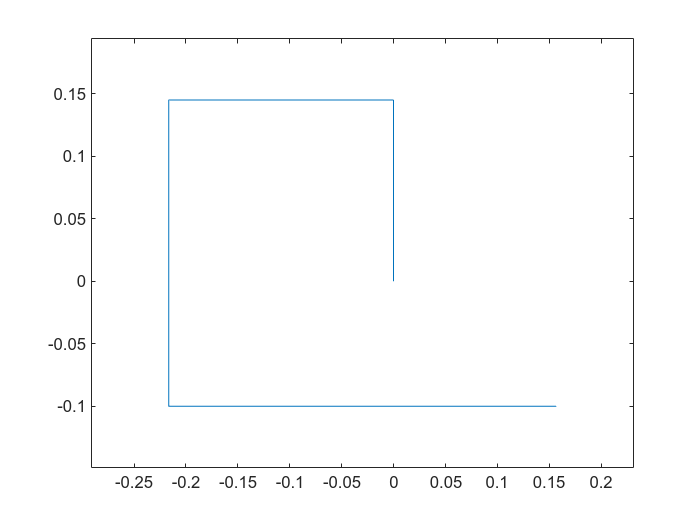

figure;
plot(posGlobal(:,1), posGlobal(:,2))
% Calculate the range for x and y axes
xMin = min(posGlobal(:,1));
xMax = max(posGlobal(:,1));
yMin = min(posGlobal(:,2));
yMax = max(posGlobal(:,2));

% Define margins for both axes (optional)
xMargin = 0.2 * (xMax - xMin);  % 20% margin for x-axis
yMargin = 0.2 * (yMax - yMin);   % 20% margin for y-axis

% Set axis limits to center the data
xlim([xMin - xMargin, xMax + xMargin]);
ylim([yMin - yMargin, yMax + yMargin]);